## Projekt HA1 MdR

clear
clc
close all

Definition der Variablen:

m = 1;
l =25;
k = 10;
g = 9.81;

### Aufgabe 1: 

Ruhelage:

 
$$\dot{\phi_0}= \ddot{\phi_0}= 0
$$



$$mg\cdot sin(\phi_0)=l^{-1}M_{A,0} \\
M_{A,0}=mgl\cdot sin(\phi_0)$$


### Aufgabe 2:

Größen einführen: 


$$u = M_A\\
x_1 = \phi\\
x_2 = \dot{\phi}\qquad \dot{x_2} = \ddot{\phi}$$


DGL umstellen:


$$\dot{x_1} = x_2\\
\dot{x_2}=-\frac{k}{lm}x_2-\frac{g}{l}sin(x_1)+\frac{1}{l^2m}u$$


DGl - System aufstellen:


$$\left\lbrack \begin{array}{c}
\dot{x_1 } \\
\dot{x_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{g}{l} & -\frac{k}{l\cdot m}
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
\sin \left(x_1 \right)\\
x_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
\frac{1}{l^2 \cdot m}
\end{array}\right\rbrack \cdot u$$


### Aufgabe 3:

phi_0   = 105;
M_0     = m*g*l*sind(phi_0)

M_0 = 236.8933


$$M_0 = u_0 = 236,89\frac{kg\cdot m^2}{s^2}\qquad \phi_0 = x_{1,0} = 105°\qquad \dot{\phi_0}=\ddot{\phi_0} = \dot{x_1} = \dot{x_2} = 0$$


Partielle Integration zur linearisierung:


$$\frac{\partial f_1}{\partial x_1}(\underline{x_0},u_0) =0\\
\frac{\partial f_1}{\partial x_2}(\underline{x_0},u_0) =1\\
\frac{\partial f_2}{\partial x_1}(\underline{x_0},u_0) =-\frac{g}{l}\cdot cos(\phi_0)\\
\frac{\partial f_2}{\partial x_2}(\underline{x_0},u_0) =-\frac{k}{lm}\\
\frac{\partial f_1}{\partial u}(\underline{x_0},u_0) =0\\
\frac{\partial f_2}{\partial u}(\underline{x_0},u_0) =\frac{1}{l^2m}$$


Daraus folgt:


$$\underline{\underline{A} } =\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{g}{l}\cdot \cos \left(\phi_0 \right) & -\frac{k}{l\cdot \;m}
\end{array}\right\rbrack$$


und


$$\underline{\underline{B} } =\left\lbrack \begin{array}{c}
0\\
\frac{1}{l^2 \cdot m}
\end{array}\right\rbrack$$


### Aufgabe 4:


$$det(\underline{\underline{A}}-\lambda \cdot \underline{\underline{I}} ) = 0$$



$$\begin{array}{l}
\textrm{det}\left(\left\lbrack \begin{array}{cc}
-\lambda  & 1\\
-\frac{g}{l}\cdot \cos \left(\phi_0 \;\right) & -\frac{k}{l\cdot \;m}-\lambda 
\end{array}\right\rbrack \right)=-\lambda \cdot \left(-\frac{k}{l\cdot \;m}-\lambda \right)-1\cdot \frac{g}{l}\cdot \cos \left(\phi_0 \;\right)=0\\
-\lambda \cdot -\frac{k}{l\cdot m}+\lambda^2 -\frac{g}{l}\cdot \cos \left(\phi_0 \right)=0
\end{array}$$


mit 

q   = -(g/l)*cosd(phi_0)

q = 0.1016

p   = k/(l*m)

p = 0.4000


$$\lambda_{1,2} =-\frac{p}{2}\pm \sqrt{{\left(\frac{p}{2}\right)}^2 -q}$$


folgt

ew_1    =-p/2 + sqrt((p/2)^2-q)

ew_1 = -0.2000 + 0.2481i

ew_2    =-p/2 - sqrt((p/2)^2-q)

ew_2 = -0.2000 - 0.2481i


$$\begin{array}{l}
\lambda_1 =-0,2+i\cdot 0,248\\
\lambda_2 =-0,2-i\cdot 0,248
\end{array}$$


Die Eigenwerte sind komplex konjugiert, da der Realteil <0 verhält sich das Sytem stabil.

Der Dämpfungsgrad und die ungedämpfte Eigenkreisfrequenz ergeben sich zu

w_0     = sqrt(0.2^2+0.248^2)

w_0 = 0.3186

D = -(0.2/w_0)

D = -0.6278

$D=-0,6278$ und $\omega_0 =0,3186$

### Aufgabe 5:

rückgefuhrt wird nur ${\phi =\;x}_1$damit ist $y=\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack \cdot \underline{x} +0\cdot u$ und $\underline{\underline{C} } =\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack$

nach umstellen der aus dem Blaockschaltbild abgeleiteten Gleichung gilt


$$\underline{\dot{x} } =\left(\underline{\underline{A} } -\underline{b} \cdot k_{\textrm{reg}} \cdot \underline{\underline{C} } \right)\cdot \underline{x}$$


Mit $\underline{\underline{A^* } } =$$\left(\underline{\underline{A} } -\underline{b} \cdot k_{\textrm{reg}} \cdot \underline{\underline{C} } \right)$

wobei $\left(\underline{b} \cdot k\cdot \underline{\underline{C} } \right)=\left\lbrack \begin{array}{c}
0\\
\frac{1}{l^2 \cdot m}
\end{array}\right\rbrack \cdot k_{\textrm{reg}} \cdot \left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 0\\
\frac{k_{\textrm{reg}} }{l^2 \cdot k} & 0
\end{array}\right\rbrack$

und damit $\underline{\underline{A^* } } =\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{g}{l}\cdot \cos \left(\phi_0 \;\right)-\frac{k_{\textrm{reg}} }{l^2 \cdot k} & -\frac{k}{l\cdot \;m}
\end{array}\right\rbrack$

### Aufgabe 6:


$$det(\lambda \cdot \underline{\underline{I}} - \underline{\underline{A^*}}) = 0$$



$$\begin{array}{l}
\textrm{det}\left(\left\lbrack \begin{array}{cc}
-\lambda  & 1\\
-\frac{g}{l}\cdot \cos \left(\phi_0 \;\right)-\frac{k_{\textrm{reg}} }{l^2 \cdot k} & -\frac{k}{l\cdot \;m}-\lambda 
\end{array}\right\rbrack \right)=-\lambda \cdot \left(-\frac{k}{l\cdot \;m}-\lambda \right)-\left(1\cdot -\frac{g}{l}\cdot \cos \left(\phi_0 \;\right)-\frac{k_{\textrm{reg}} }{l^2 \cdot k}\right)=0\\
\lambda^2 -\frac{k}{l\cdot \;m}\cdot \lambda +\frac{g}{l}\cdot \cos \left(\phi_0 \;\right)+\frac{k_{\textrm{reg}} }{l^2 \cdot k}=0
\end{array}$$


mit der pq-Formel folgt dass

$\lambda_{1,2} =\frac{p}{2}\pm \sqrt{{\left(\frac{p}{2}\right)}^2 -q}$ wobei $p=-\frac{k}{l\cdot m}=-0,4$

für den gefordertren Däpfungsgrad D=-0,7 müssen die eigenwerte komplex konjugiert sein, also die form

$\lambda_{1,2} =\sigma \;\pm i\cdot \omega$ haben wobei $\sigma =-\frac{p}{2}=-0,2$ist.

mit $D=-\frac{\omega }{\sqrt{\omega^2 +\sigma {\;}^2 }}=0,7$folgt daraus dass 

D = -0.7;
sigma = -p/2;
omega = -sqrt((-sigma/D)^2 -sigma^2)

omega = -0.2040


$$\omega =\sqrt{{\left(-\frac{\sigma }{-D}\right)}^2 -\sigma^2 }=0,204$$


also muss $\sqrt{{\left(\frac{p}{2}\right)}^2 -\left(+\frac{g}{l}\cdot \cos \left(\phi_0 \right)+\frac{k_{\textrm{reg}} }{l^2 \cdot k}\right)}=i\cdot 0,204$ sein.

k_reg = l^2*k*((0.2)^2-g/l*cosd(phi_0)+0.204^2)

k_reg = 1.1449e+03

(0.2)^2+g/l*cosd(phi_0)+0.204^2

ans = -0.0199

Der Verstärkungsfaktor berechnet sich zu $k_{\textrm{reg}} =-1145$.

### Aufgabe 7

% Anfangszustände
x(:,1)  = [75; 0];
dx(:,1) = [0,0];
u       = M_0;

% Zeitintervall
t_0     = 0;
dt      = 0.01;
t_end   = 20;

t_k     = t_0:dt:t_end;

#### nichtlinear, ungeregelt, euler

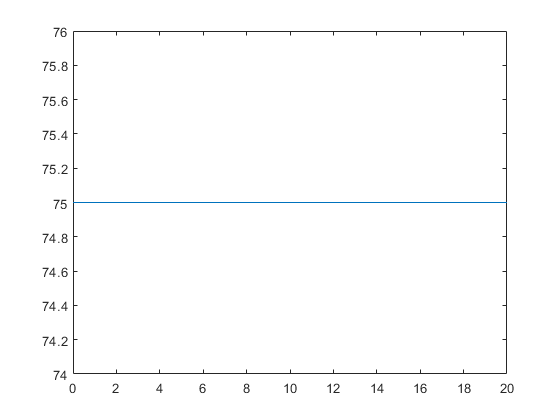


%Simulation
for i=2:length(t_k)
    x(:,i) = x(:,i-1) + dt * nichtlin_ungeregelt(x(:,i-1),u,l,m,k,g);
end

% Plot
plot(t_k,x(1,:))

#### linear, ungeregelt

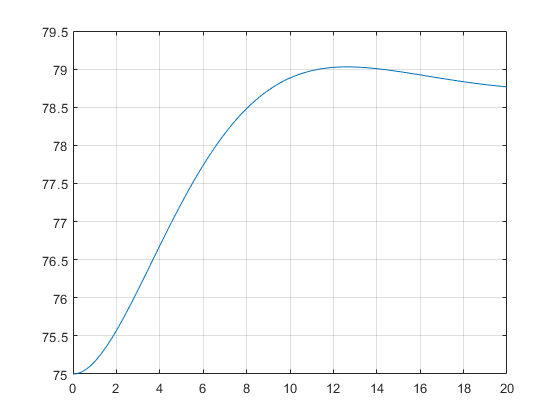

%Simulation
for i=2:length(t_k)
    dx(:,i) = dx(:,i-1) + dt * lin_ungeregelt(dx(:,i-1),M_0,l,m,k,g);
end

x = x + dx;

% Plot
plot(t_k,x(1,:))
grid on

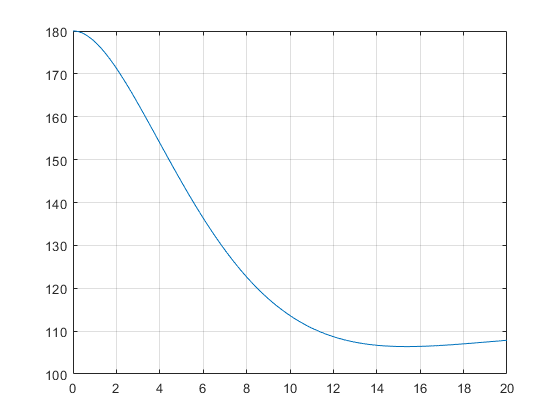

%Simulation
for i=2:length(t_k)
    x(:,i) = x(:,i-1) + dt * lin_geregelt(x(:,i-1),M_0,l,m,k,g,k_reg);
end

% Plot
plot(t_k,x(1,:)+phi_0)
grid on